# Parameter Estimation for Discrete-SIR models

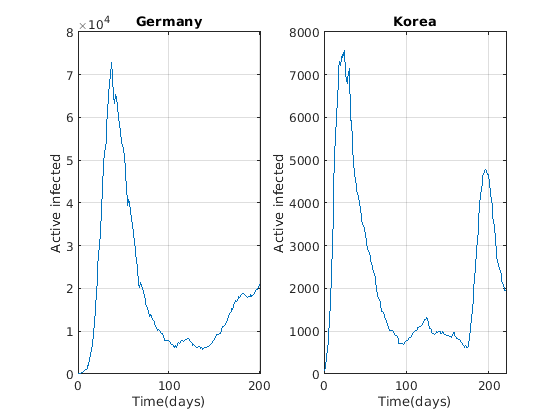

Localities = ["Germany", "Korea"];

time = {40:240; 30:250};
Population = [8.3e7; 5.1e7];
ydata = cell(length(Localities),1);

for i = 1: length(Localities)
    load('../Data/' + Localities(i) + '.mat')
    ydata_aux = [Cases - Recovered - Death; Recovered];
    ydata{i} = ydata_aux(:,time{i});
end

figure
subplot(1,2,1)
plot(ydata{1}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{1})

subplot(1,2,2)
plot(ydata{2}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{2})

Parameter estimation model simple, complex and classic probabilities  

VarNames = {'N','I_f','I_q','I_j','R','R_j'};
OutNames = {'S_f','S_q','I_f','I_q','I_j','R','R_j','N','\aleph', 'G(t)', 'Cum(I_q)'};
ParNames = {'a','\lambda','\alpha','\mu', '\theta', '\gamma', '\nu', 'z', '\beta'};

FullNames = [VarNames, ParNames];

ModelNames = ["Simple", "Complex", "Classic","ClassicNO"];

T_save = cell(length(Localities), length(ModelNames));  

ModelfncName = "CHIMERA_FQ";

for k = 1:length(Localities)
% for k=1:1
    RealData = ydata{k};    
    
    Range1 = [
        Population(k) Population(k);    %N
        0 1000;                         %I_f                
        0 0;                            %I_q
        RealData(1,1) RealData(1,1);    %I_j
        RealData(2,1) RealData(2,1);    %R_total
        RealData(2,1) RealData(2,1);    %R_j
        ];
    
    Range2 = [
                0 1;        %a    
                0 1;        %lambda 
                0 1;        %alpha
                0 0;        %mu 
                0 1;        %theta
                0 1;        %gamma 
                0 1000;     %nu 
                0 30;       %z 
                0 1         %beta 
    ];
    
    RangeT = [Range1; Range2];
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    N = 10000;
    extra = struct();
    Parameters = [];
    Res = [];
     
    for i = 1:4
%     for i = 4:4    
        extra.Prob = i;
        %%Prob = 1 -> psi(simple)
        %%Prob = 2 -> phi(complex)
        %%Prob = 3 -> classical+ aleph
        %%Prob = 4 -> classical
        
        [T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);
        outs = 5; 
        T.Properties.CustomProperties.output = outs;
        
        if i == 3
            %z
            T.Range(end-1,:) = [0 0];
            T.Nominal(end-1) = 0;
            %beta
            T.Range(end,:) = [0 1];
            T.Nominal(end) = 0.5;
        end
        
        if i == 2
            %z
            T.Range(end-1,:) = [0 300];
        end
        
        if i == 4
            %z
            T.Range(end-1,:) = [0 0];
            T.Nominal(end-1) = 0;
            %beta
            T.Range(end,:) = [0 1];
            T.Nominal(end) = 0.5; 
            %nu
            T.Range(end-2,:) = [0 0];
            T.Nominal(end-2) = 0;
        end
        
        T_save{k, i} = T;
        
        Solver = 'fmincon';
           
        Opt = optimoptions('fmincon', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
            'MaxIterations', 3000, 'Display','off');
%         
%         parfor j = 1:N
%     %     for j = 1:N
%             [T_aux, Res_aux] = gsua_pe(T, xdata, RealData(1,:),...
%                 'solver', Solver,'N', 1,'opt', Opt,'save', false);
%             Parameters(:,j) = T_aux.Estfmincon;
%             Res(j) = Res_aux;
%         end
%         
%         [Res, idx] = sort(Res);
%         Parameters = Parameters(:,idx);     
%         T_save{i}.Nominal = Parameters(:,1);
%         save("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i), "Res",  "Parameters")
%         
%         figure
%         gsua_eval(Parameters(:,1), T_save{k, i}, xdata, RealData(1,:));
%         suptitle(ModelNames(i) + " residual: " + Res(1) + " Locality:" + Localities{k})
    end
end

Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function


[T,~] = gsua_dataprep(ModelfncName, RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);

Setting environment to work with user-defined function


outs = 5; 
T.Properties.CustomProperties.output = outs;
T_aux = [];
for k = 1:length(Localities)
%     Localities(k)
    for i = 1:4
    load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))
    T_aux = [T_aux, Parameters(:,1)];
%     ModelNames(i)
    end
end
T.Params = T_aux;
T

T = 9×3 table
                 Range      Nominal       Params   
               _________    _______    ____________

    I_f        0    1000      500      [1×8 double]
    a          0       1      0.5      [1×8 double]
    \lambda    0       1      0.5      [1×8 double]
    \alpha     0       1      0.5      [1×8 double]
    \theta     0       1      0.5      [1×8 double]
    \gamma     0       1      0.5      [1×8 double]
    \nu        0    1000      500      [1×8 double]
    z          0      30       15      [1×8 double]
    \beta      0       1      0.5      [1×8 double]


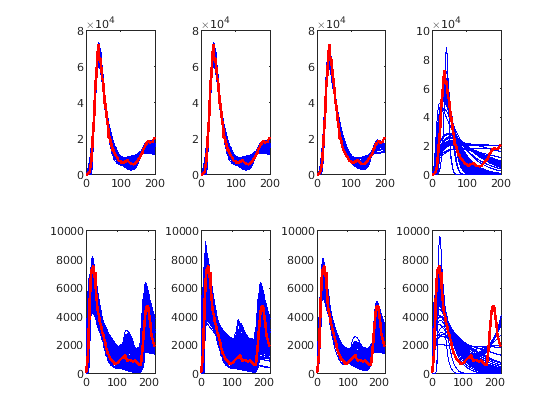

counter = 1;
figure
I = zeros(8,1);
for k = 1:length(Localities)
    RealData = ydata{k};
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1; 
    y_sim = [];
    for i = 1:4
        load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))
        F = find(Res <= min(Res)*5);
        I(counter) = length(F);
        parfor j = 1:length(F)
            y_sim(j,:) = gsua_deval(Parameters(:,j),T_save{k, i},xdata);
        end
        subplot(2,4,counter)
        plot(xdata, y_sim,'b')
        hold on
        plot(xdata,RealData(1,:),'r',"LineWidth",2)
        counter = counter + 1;
        xlabel('Time (days)')
    end
end

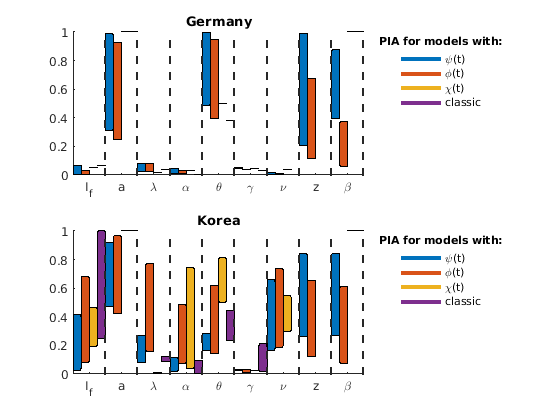

close all
figure 
counter = 1;
for k = 1:2
    subplot(2,1,k)
    FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/COVID19/";
    A = rand(4,3);
    cm = colormap(lines(size(A,1)));
    x=[];
    mx=[];
    P=[];
    
    for i=1:4
            
        load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))
        P = (Parameters(:,1:I(counter))-T_save{k, i}.Range(:,1))./(T_save{k, i}.Range(:,2)-T_save{k, i}.Range(:,1));
        
        for j = 1:9
            if (i ~= 4 || j ~= 7 && j~=8) 
               if (i ~= 3 || j ~= 8)  
                    Pq = rmoutliers(P(j,:),'percentiles', [10 90]);
                    Pq = quantile(Pq',[0.25 0.75])';
            %         Pq = [min(Pq) max(Pq)]';
                    rectangle('Position',[j+0.25*(i-1) Pq(1) 1/4 Pq(2)-Pq(1)],'FaceColor',[cm(i,:),0.5],'Curvature',0.2)
                    hold on
            %         text(0,j+0.75,string(T_save{k, i}.Properties.RowNames(j)))
                end
            end            
                x(j) = j+1;
                xline(x(j),'--','linewidth', 1.5)
                if j>1
                    mx(j) = x(j-1)+(x(j)-x(j-1))/2;
                else
                    mx(j) = (x(j)+1)/2;
                end          
        end
        counter = counter + 1;
    end

    xlim([1 10])
    ylim([0 1])
    xticks(mx)
    set(gca,'XTickLabel',T_save{k, i}.Properties.RowNames,'TickLabelInterpreter', 'tex')
    title(Localities(k))    
    
    h1 = plot(-100, -110,'color', cm(1,:),"LineWidth",3);
    h2 = plot(-100, -110,'color', cm(2,:),"LineWidth",3);
    h3 = plot(-100, -110,'color', cm(3,:),"LineWidth",3);
    h4 = plot(-100, -110,'color', cm(4,:),"LineWidth",3);
          
    lgd = legend([h1; h2; h3; h4],"\psi(t)", "\phi(t)","\chi(t)","classic", "box",'off','Location',"bestoutside");
    title(lgd,'PIA for models with:')
end

savefig(FolderFigures + "PIA_COVID19.fig")
saveas(gcf, FolderFigures + "PIA_COVID19.png")

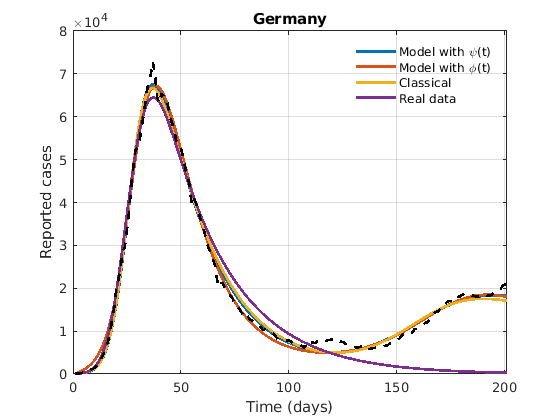

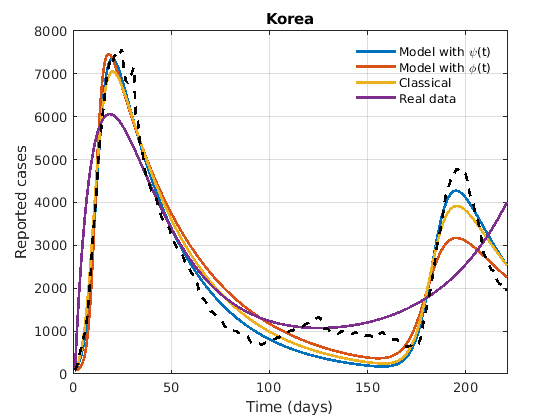

close all

FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/COVID19/";

Titles = ["Model with \psi(t)"; 
    "Model with \phi(t)";
%     "Model with \chi(t)";
    "Classical"
    "Real data"];

counterOUt = 1;
for k = 1:length(Localities)
    figure
    A = rand(4,4);
    cm = colormap(lines(size(A,1)));
    
    counter = 1;
    RealData = ydata{k};    
    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    for i = 1:4
        load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))

        T_save{k,i}.Properties.CustomProperties.output = 5;
        
        ysim = gsua_deval(Parameters(:,1)', T_save{k,i}, xdata);
                
        [~, Idx] = sort(Res);

        plot(ysim', 'Color', cm(i,:),'LineWidth',2); 
        hold on
        grid on
        counter = counter +1;
        xlim([0 length(RealData)]);
    end
    
    title(Localities(k))
    
    xlabel("Time (days)")
    ylabel("Reported cases")
    hold on
    plot(RealData(1,:)','--k','LineWidth',2)
    legend(Titles,"box","off")  
    counterOUt = counterOUt + 1;
    
savefig(FolderFigures + "Fit_COVID19_"+Localities(k)+".fig")
saveas(gcf,FolderFigures + "Fit_COVID19_"+Localities(k)+".png")
end

## Probabilities vs time

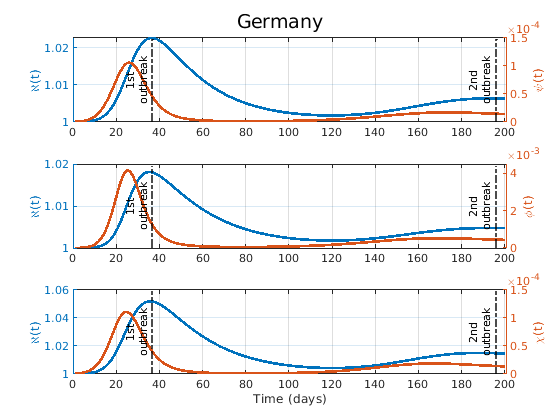

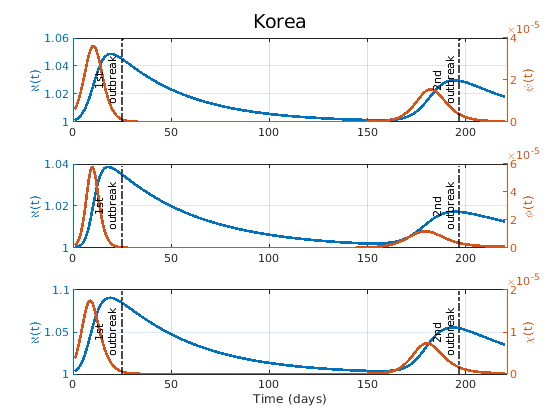

IdxSims = [];
Titles = ["Infected with \psi(t)"; 
    "Infected with \phi(t)";
    "Infected with classic"];
Prob = ["\psi(t)", "\phi(t)", "\chi(t)"];

for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure
    suptitle(Localities(k))
    
    MaxValue1 = find(RealData(1,1:100) == max(RealData(1,1:100)));
    MaxValue2 = 150 + find(RealData(1,150:end-6) == max(RealData(1,150:end-6)));
    
    for i = 1:3
        
        load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))

        T_save{k,i}.Properties.CustomProperties.output = [9,10];

        ysim = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);

        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
    
        subplot(3,1,counter)
        yyaxis left
        
        plot(squeeze(ysim(1, 2:end))', 'LineWidth',2); 
        ylabel("\aleph(t)")            
        hold on
        yyaxis right
        plot(squeeze(ysim(2, 2:end))', 'LineWidth',2); 
        ylabel(Prob(counter))
        
        counter = counter +1;
        xlim([0 length(RealData)]);
        xl = xline(MaxValue1,'-.k', {'1st'; 'outbreak'}, "linewidth",1.5);
            xl.LabelVerticalAlignment = 'middle';
            xl.LabelHorizontalAlignment = 'left';
            xl.FontSize = 8;    
        xl =xline(MaxValue2,'-.k', {'2nd'; 'outbreak'}, "linewidth",1.5);
            xl.LabelVerticalAlignment = 'middle';
            xl.LabelHorizontalAlignment = 'left';
            xl.FontSize = 8;    
        grid on
        
        
%         if i==1
%            legend("\aleph(t)","Probability",'location',"best","box","off")
%         end
        
    end

    xlabel("Time (days)")    
    savefig(FolderFigures + "Probs_" + Localities(k) + "Discrete.fig")
    saveas(gcf,FolderFigures + "Probs_" + Localities(k) + "Discrete.png")
end

## All states

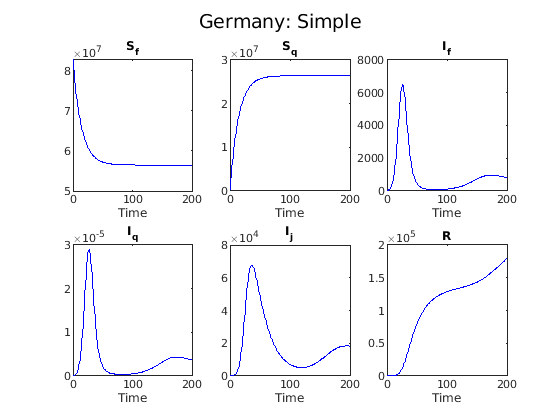

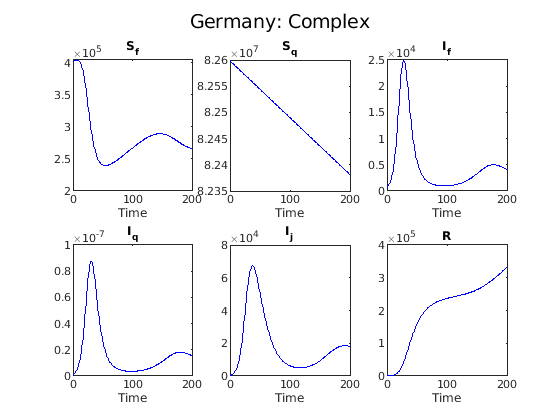

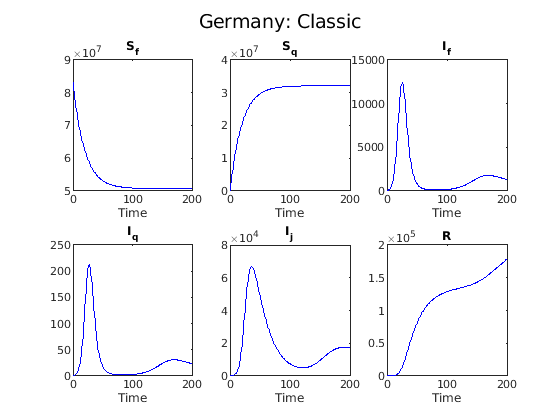

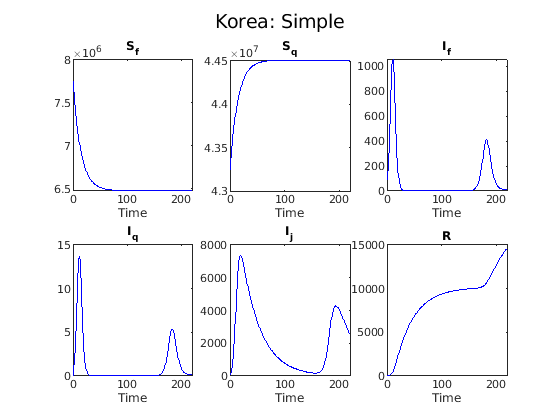

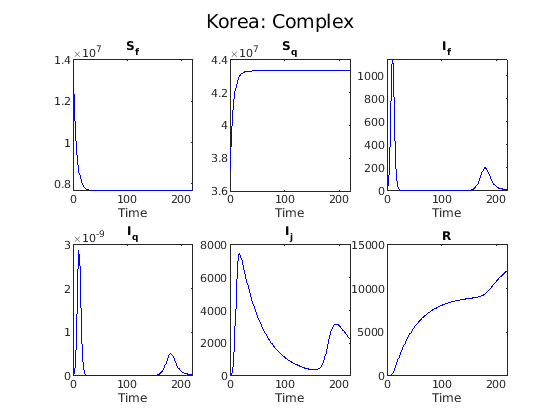

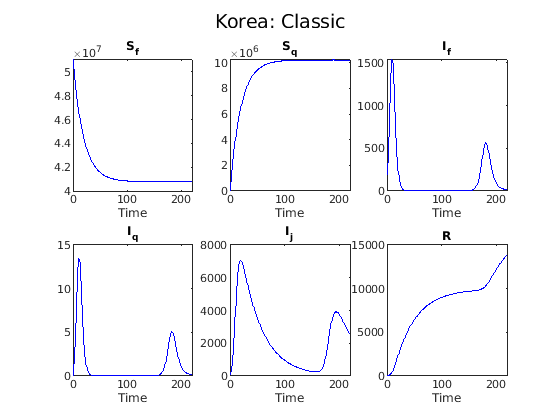

for k = 1:length(Localities)
    counter = 1;
    RealData = ydata{k};    
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    figure
    for i = 1:3
        load("ResultsCovid/Estimations_Disc_beta_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        ysim = zeros(N, 2, D);
        T_save{k,i}.Properties.CustomProperties.output = 1:6;
        figure
        gsua_eval(Parameters(:,1), T_save{k,i}, xdata);
        suptitle(Localities(k) + ": " + ModelNames(i))
    end 
end